# LAB 4 -TrevorCallow- MAT 275

# Exercise 1

### **Part (a)**

type 'LAB04ex1b.m'

t0 = 0; tf = 50; y0 = [1;0];
[t,Y] = ode45(@f,[t0,tf],y0);
u1 = Y(:,1); u2 = Y(:,2);

figure(1)
hold on;
plot(t, u1, 'b-+');ylabel('u1');
plot(t, u2, 'ro-');ylabel("v(t)=y'(t)'");
legend('y(t)', 'v(t)');
ylim([-2.1, 2.1])
hold off;

figure(2)
plot(u1, u2);
axis square;
xlabel('u1');
ylabel('u2');
ylim([-2.1, 2.1])
xlim([-2.1, 2.1])

A = [t, Y(:,1), Y(:,2)];
index = abs(A(:,2:3)) >= 0.025;

%----------------------------------------------------------------------
function dydt = f(t,Y)
    y = Y(1); v = Y(2);
    dydt = [ v ; -sin(t) - 2*v - 4*y ];
end


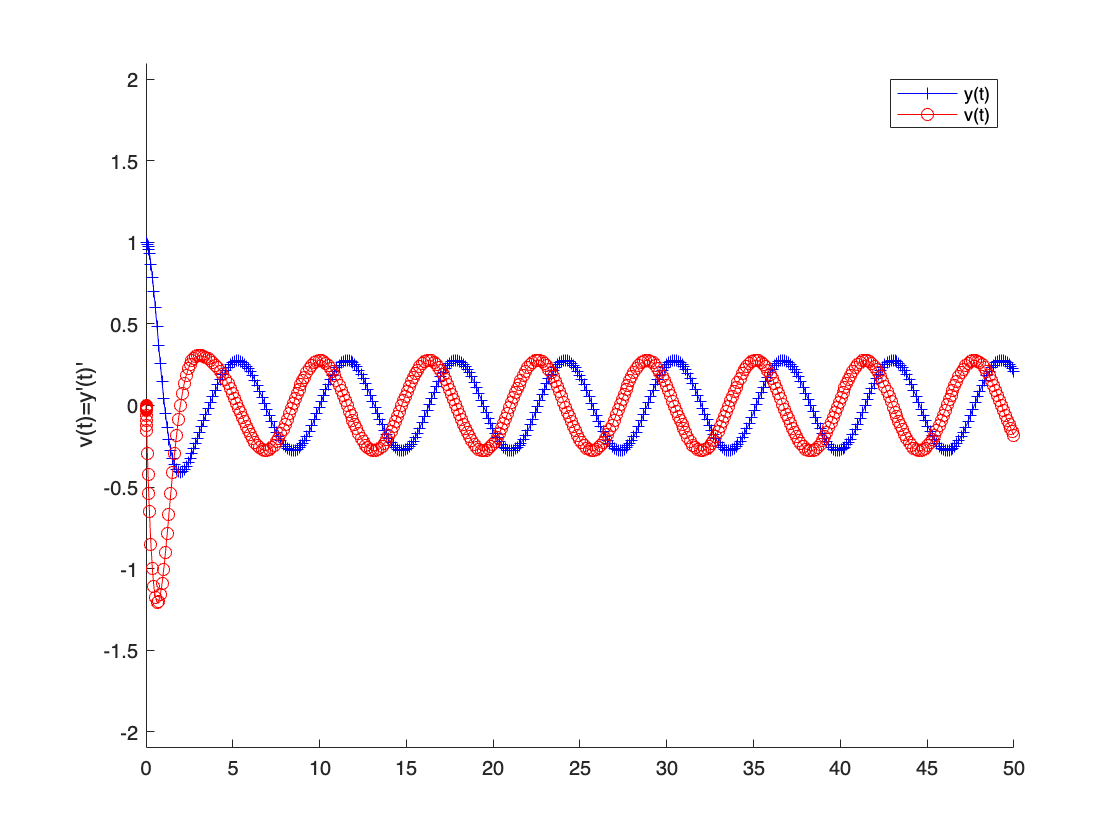

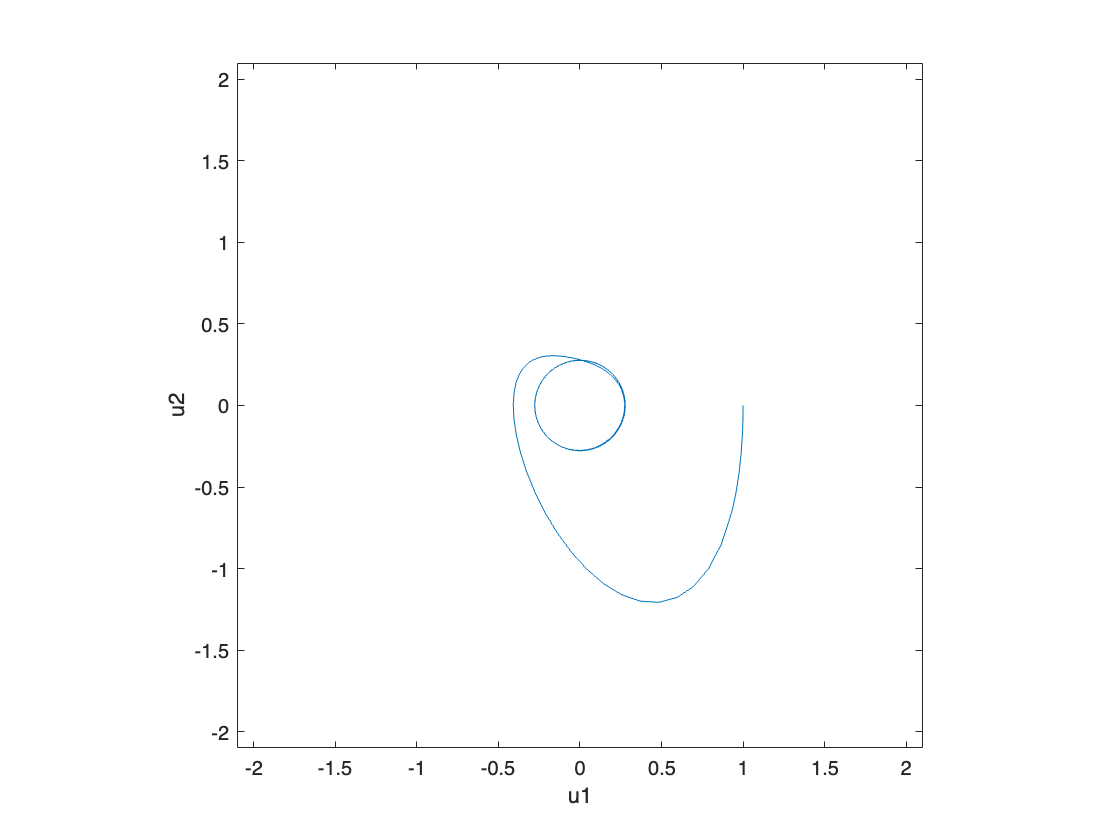

LAB04ex1b

### **Part (b)**

%1.25594321575479e-05
%Tvalues
%2.51188643150958e-05
%3.76782964726437e-05
%5.02377286301916e-05
%0.000113034889417931
%0.000175832050205671
%0.000238629210993410
%0.000301426371781150
%0.000615412175719847
%0.000929397979658545
%0.00124338378359724
%0.00155736958753594
%0.00312729860722943
%0.00469722762692292
%0.00626715664661640
%0.00783708566630989
%0.0156867307647773
%0.0235363758632448
%0.0313860209617122
%0.0392356660601796
%0.0784838915525168
%0.117732117044854
%0.156980342537191
%Yvalue
%0.999999999684524	-5.02371765418548e-05
%0.999999998738104	-0.000100473248904395
%0.999999997160754	-0.000150708217083659
%0.999999994952489	-0.000200942081075688
%0.999999974447912	-0.000452094838088734
%0.999999938172523	-0.000703219989827277
%0.999999886128053	-0.000954317535797148
%0.999999818316237	-0.00120538747550466
%0.999999242807642	-0.00246032306286135
%0.999998273375448	-0.00371456841988278

*do not print the entire vectors t and Y, but include a few values which show where the last three maxima occur*

### Part (c)

**The long term behavior is that it will contiue to repeat until it reaches 0**

### **Part (d)**

**NOTE: ***create a file "LAB04ex1d" which is a duplicate of LAB04ex1, but with the initial conditions for y and v changed. figure(1) and figure(2) also need to be changed to figure(3) and igure(4) (in order to plot part a and part d on separate figures so they can be compared). Delete this note upon submission.*

type LAB04ex1d

t0 = 0; tf = 50; y0 = [1;0];

[t,Y] = ode45(@f,[t0,tf],y0);
u1 = Y(:,1); u2 = Y(:,2);    % y in output has 2 columns corresponding to u1 and u2
figure(1);
hold on
plot(t,u1,'b-+'); ylabel('t');
plot(t,u2,'ro-'); ylabel("v(t)=(y')""(t)");
legend("y(t)","v(t)")
ylim([-2.1,2.1])
hold off
figure(2)
plot(u1,u2);
axis square;
xlabel('u1');
ylabel('u2');
ylim([-2.1,2.1])
xlim([-2.1,2.1])
A= [ t,Y(:,1),Y(:,2)]
index= abs(A(:,2,3)) >=.025
 %----------------------------------------------------------------------
function dydt = f(t,Y)
y = Y(1); v = Y(2);
dydt = [ v ; -sin(t)-2*v-4*y ];
end


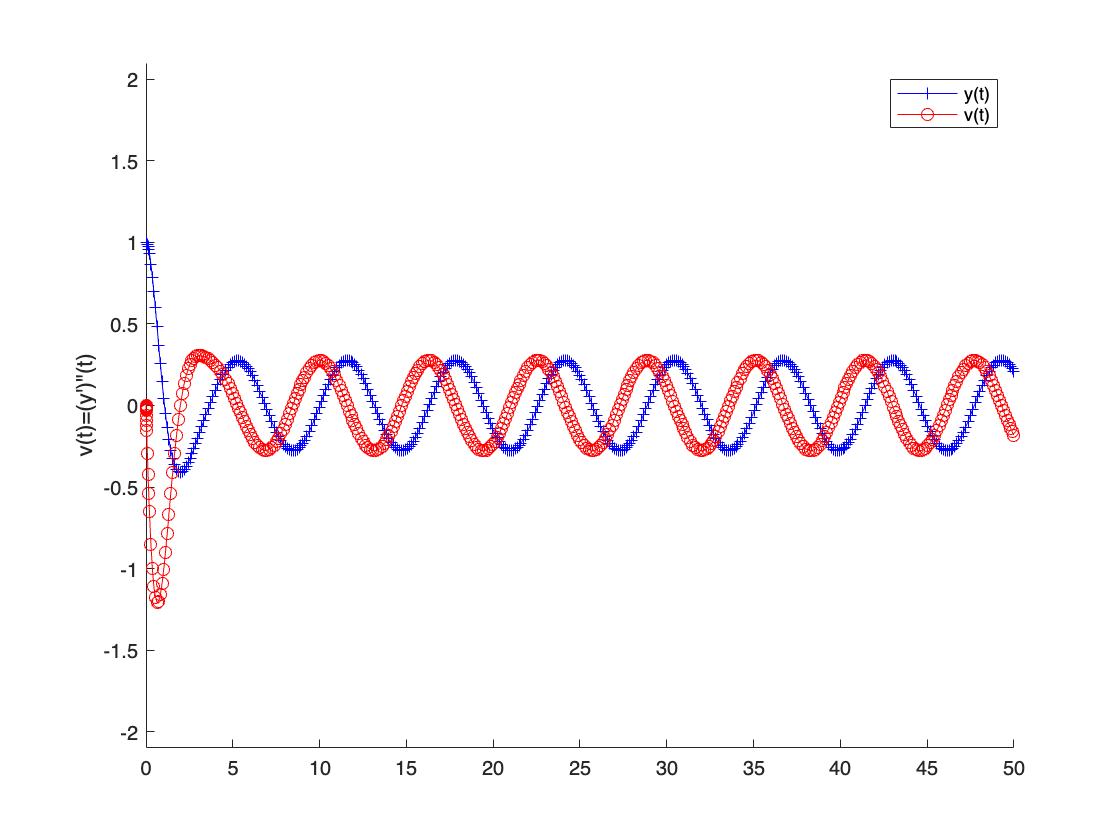

A =          0    1.0000         0
    0.0000    1.0000   -0.0001
    0.0000    1.0000   -0.0001
    0.0000    1.0000   -0.0002
    0.0001    1.0000   -0.0002
    0.0001    1.0000   -0.0005
    0.0002    1.0000   -0.0007
    0.0002    1.0000   -0.0010
    0.0003    1.0000   -0.0012
    0.0006    1.0000   -0.0025


LAB04ex1d

**The longer term behavior will continue until 0 just like the graphs previuously because they are very simliar start tyhe same way. if you look at the graphs above they are extremely similar.**

# Exercise 2

**Read the instructions in your lab pdf file carefully!**

### Part (a)

Create a new M-file with the differential equation changed

type  LAB04ex2

t0 = 0;
tf = 50;
y0 = [1,0];
[t,y] = ode45(@f,[t0,tf],y0);
u1 = y(:,1); u2 = y(:,2);
figure(5)
hold on; 
plot(t,u1,'b-+')
ylabel('u1');
plot(t,u2,'ro-')
ylabel('v(t)=y(t)');
legend('y(t)','v(t)')
ylim([-2.1,2.1])
hold off
figure(6)
plot(u1,u2);axis square;xlabel('u_1');ylabel('u_2');
ylim([-2.1,2.1])
xlim([-2.1,2.1])
A = [t, y(:,1),y(:,2)];
index = abs(A(:,2:3)) >=.025;
%
function dYdt= f(t,Y)
y=Y(1); v=Y(2);
dYdt = [v;sin(t)+2*(y^2)*v+4*y];
end


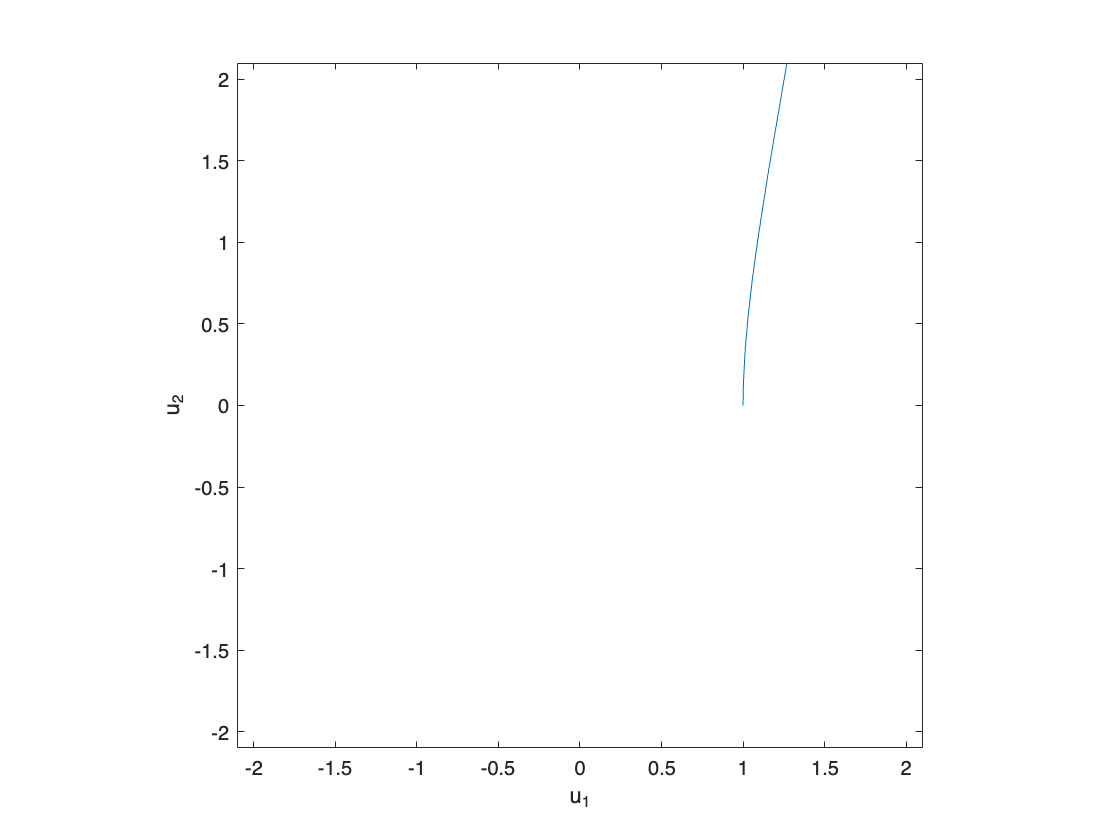

LAB04ex2

### Part (b)

### they are very similar to the previous questions however in the short term they are larger thne get smaller faster

### Part (c)

**long term behavior of both end with it eventually making it to zero, the oclations contiue to get smaller and smller unitl it reeaches zero.**

### Part (d)

You will have to create another M-file, LAB04ex2d.

**NOTE:** *there should only be ONE output plot for the code you write in LAB04ex2d. The plot should superimposes solutions for y(t) from euler.m and ode45. Include a legend to label each solution. Delete this note upon submission.*

type LAB04ex2d

t0=0;tf=50;y0=[1,0];
[t,y]=ode45(@f,[t0,tf],y0);
[te,ye]=euler(@f,[t0,tf],y0,500);
u1=y(:,1);u2=y(:,2);
figure(7)
hold on
plot(t,u1,'b-+')
ylabel('u1');
plot(t,u2,'ro-')
ylabel('v(t)=y(t)');
legend('y(t)','v(t)')
ylim([-2.1,2.1])
hold off
figure(8)
plot(u1,u2);axis square;xlabel('u_1');ylabel('u_2');
ylim([-2.1,2.1])
xlim([-2.1,2.1])
A = [t, y(:,1), y(:,2)];
index = abs(A(:,2:3)) >=.025;
%-----------------------------------------------
function dYdt= f(t,Y)
y=Y(1); v=Y(2);
dYdt = [v;sin(t)+2*(y^2)*v+4*y];
end
function [t,y] = euler(f,tspan,y0,N)
m= length(y0);
t0=tspan(1);
tf=tspan(2);
h=(tf-t0)/N;
t=linspace(t0,tf,N+1);
y=zeros(m,N+1);
y(:,1)=y0';
for n=1:N
    y(:,n+1)=y(:,n)+h*f(t(n),y(:,n));
end
t=t';y=y';
end


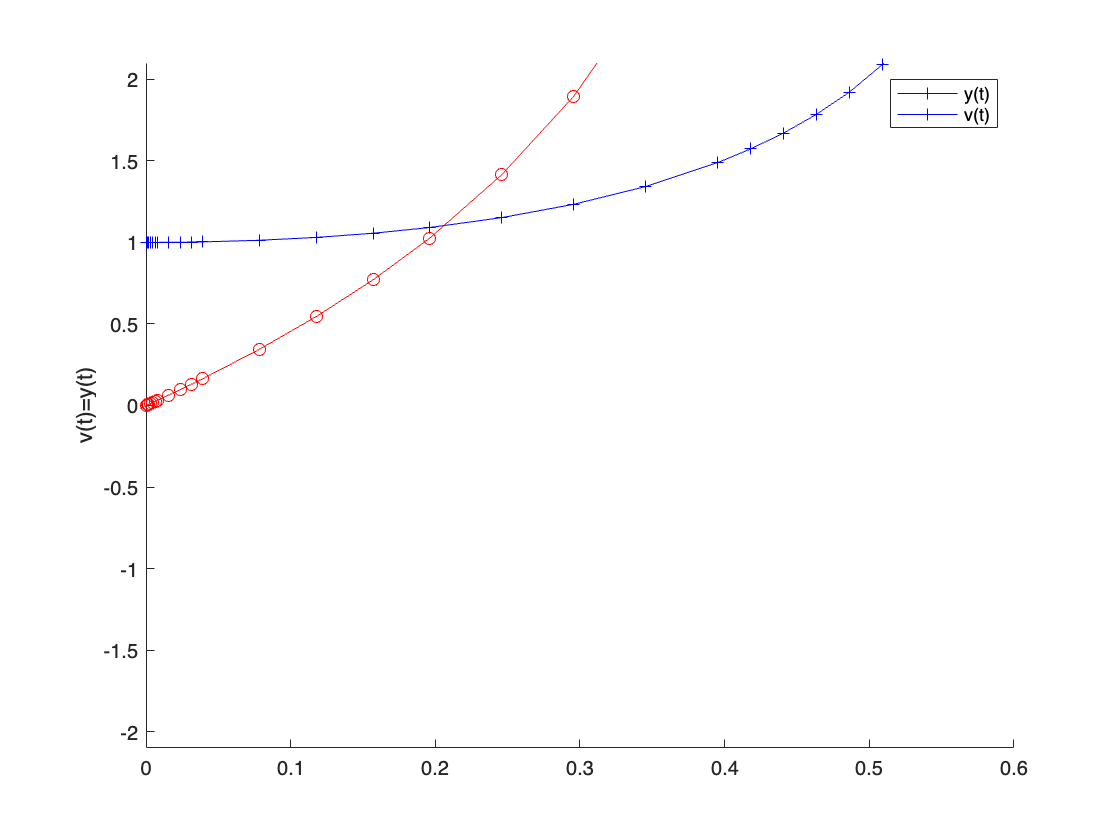

LAB04ex2d

The solutions are not identical but very similar, if you increase the value of N the ocsilations get smaller faster and the graph becomes more precise.

# Exercise 3

***NOTE: ****the code for this part should be very similar to what you wrote for EX1-A. You just need to modify the system of differential equations. It's OK if you get an error message. Delete this note upon submission.*

type LAB04ex3

t0 = 0; tf = 50; y0 = [1;0];
[t,Y] = ode45(@f,[t0,tf],y0);
u1 = Y(:,1); u2 = Y(:,2);

figure(1)
hold on;
plot(t, u1, 'b-+');ylabel('u1');
plot(t, u2, 'ro-');ylabel("v(t)=y'(t)'")
legend('y(t)', 'v(t)');
ylim([-2.1, 2.1]);
hold off;

figure(2)
plot(u1, u2)
axis square;
xlabel('u1');
ylabel('u2');
ylim([-2.1, 2.1]);
xlim([-2.1, 2.1]);

A = [t, Y(:,1), Y(:,2)];
index = abs(A(:,2:3)) >= 0.025;

%----------------------------------------------------------------------
function dydt = f(t,Y)
    y = Y(1); v = Y(2);
    dydt = [ v ; sin(t)+2*v+4*y ];
end


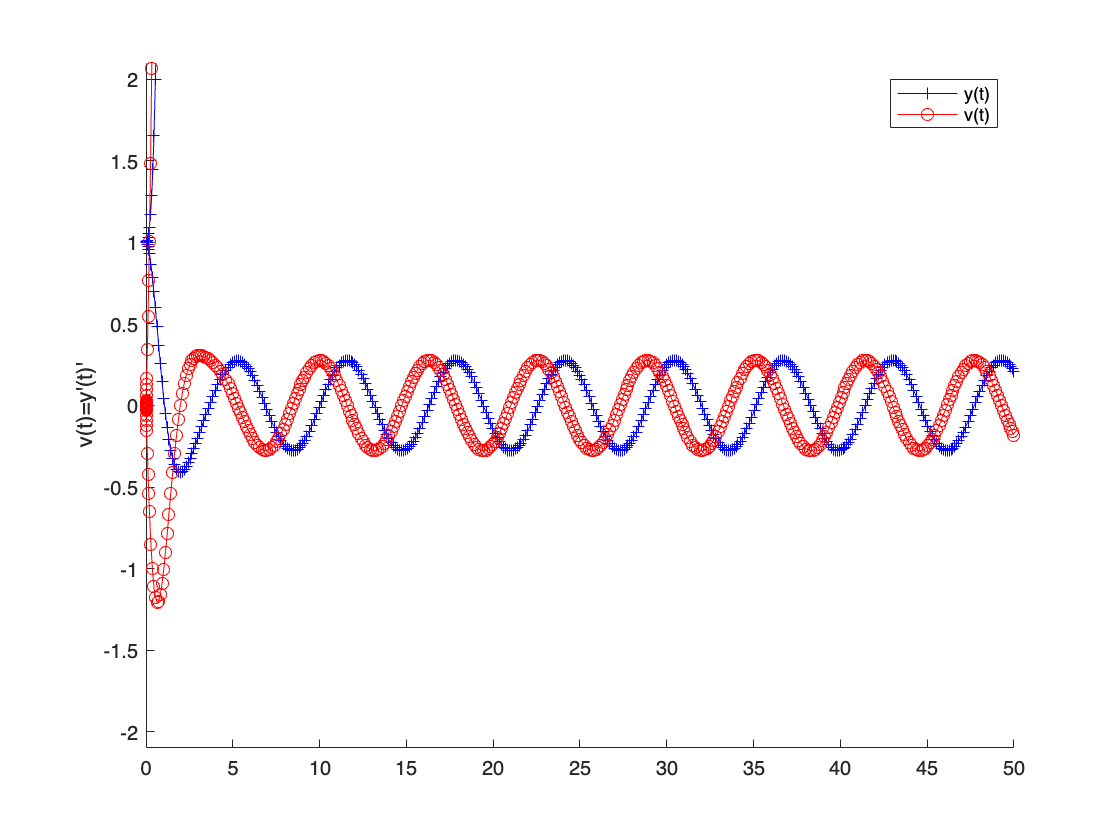

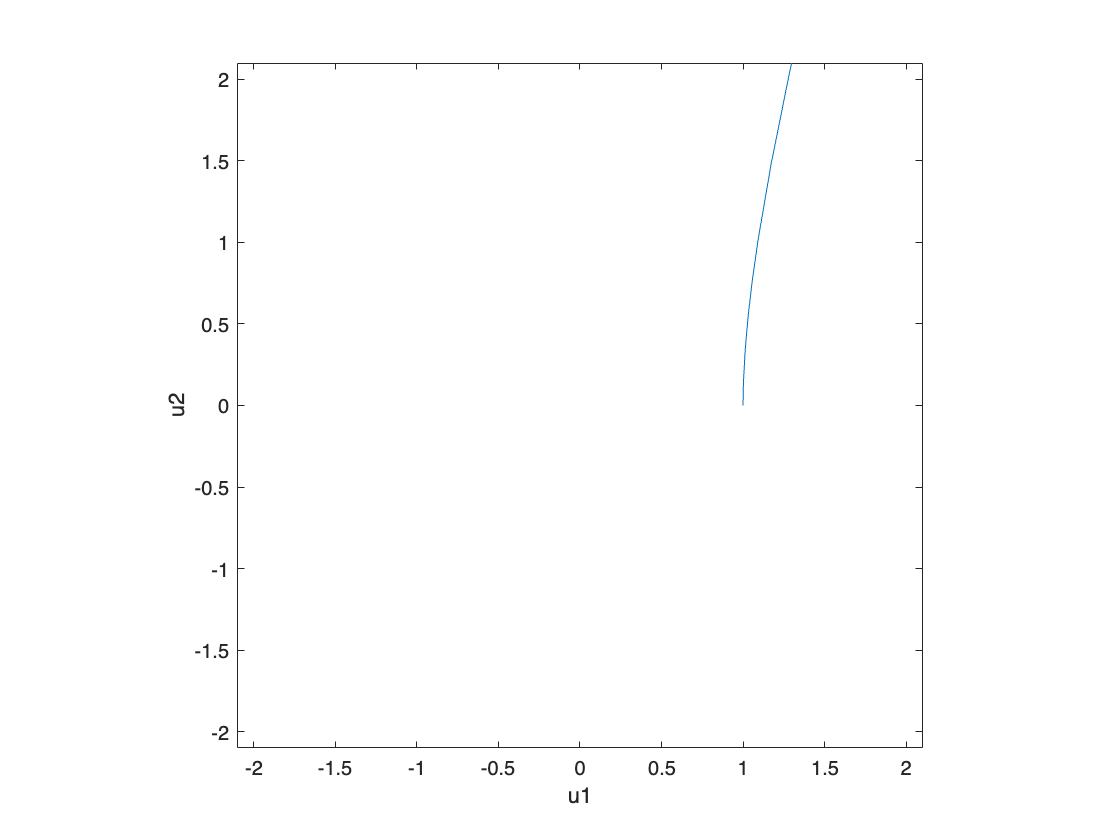

LAB04ex3

The behavior of the solution is similar to that of 7.

matlab is not giving me any warnings until problem 4

# Exercise 4

***NOTE: ****this code should also be very similar to what you wrote for EX1-A and EX3. When defining the function f at the bottom of your LAB04ex4.m file, dYdt now needs to be a column with THREE elements.  LAB04ex4 should include commands which reproduce the plots shown in the lab4 document. Delete this note upon submission.*

type LAB04ex4

t0 = 0 ; tf=50; y0= [0,0,.5];
[t,y]=ode45(@f,[t0,tf],y0);
u1 = y(:,1);u2=y(:,2);u3=y(:,3);
figure(1)
hold on
plot(t,u1,'b-+');ylabel('u1');
plot(t,u2,'ro-');ylabel("v(t)=y'(t)'");
plot(t,u3,'k-');ylabel("3v(t)=y3(t)'");
legend('y(t)','v(t)')
ylim([-2.1,2.1])
hold off
figure(2)
plot3(u1,u2,u3);
hold on
view([-40,60])
xlabel('y');ylabel('v=y');zlabel('w=y');
ylim([-2.1,2.1])
xlim([-2.1,2.1])
A=[t,y(:,1),y(:,2)];
index=abs(A(:,2:3)) >=.025;
function dYdt = f(t,Y)
y=Y(1); v = Y(2); w=Y(3);
dYdt = [v;w;cos(t)+2*(y^2)*w+4*v];
end


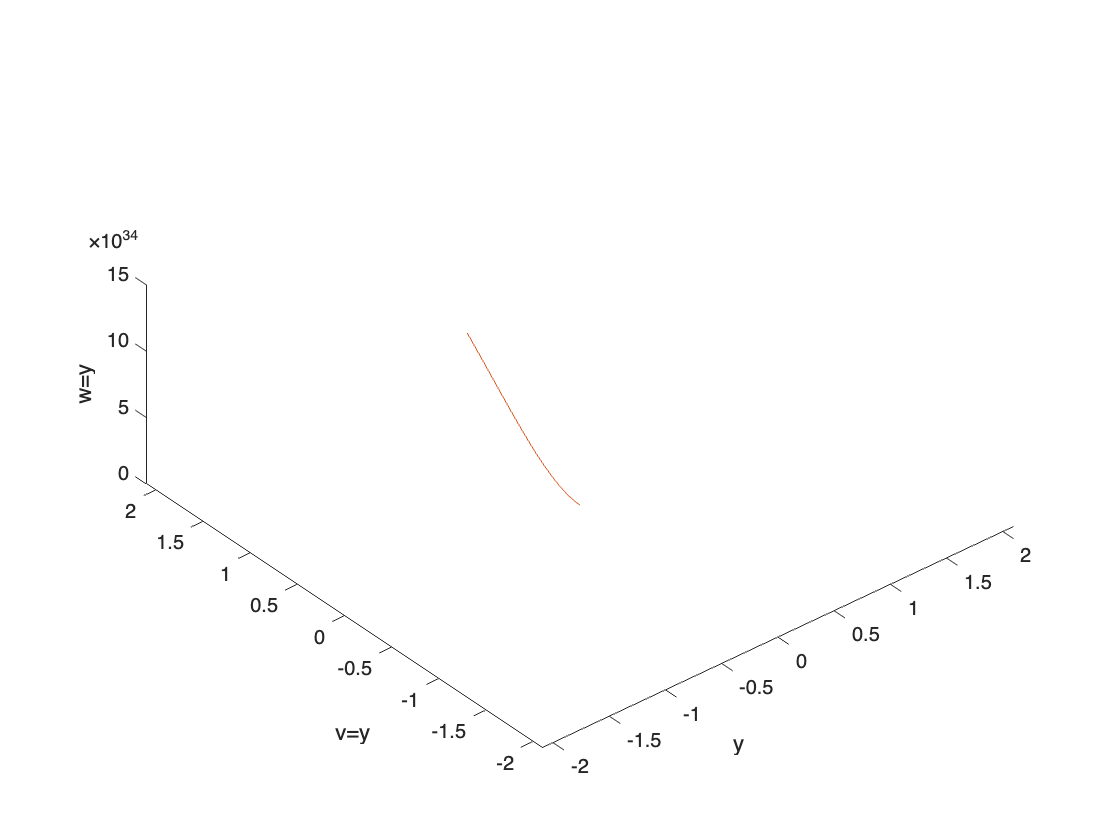

LAB04ex4